% AE675 Project
% Submitted by Chourishi

clear all

seed=170448;%Your roll number
rng(seed);
L= 0.75+0.5*rand(1,1)%length L

L = 1.1404

theta = 30 + 30*rand(1,1)%Angle theta

theta = 44.7266

TA = 500+200*rand(1,1)%Temperature at point A

TA = 533.1032



A = 6e-4

A = 6.0000e-04

K = 1;% Waste
E = 210e9

E = 2.1000e+11

alpha = 24e-6

alpha = 2.4000e-05


% alpha = 0;



% Temperature Solution
numberElements = 11;
numberNodes = 18;

unit = 0.5*L*cotd(theta);
nodeCoordinates = [
    0 0;
    unit L/2;
    2*unit L;
    3*unit L/2;
    4*unit 0;
    3*unit 0;
    2*unit 0;
    unit 0;
    5*unit L/2;
    6*unit L;
    7*unit L/2;
    8*unit 0;
    7*unit 0;
    6*unit 0;
    5*unit 0;
    2*unit L/2;
    6*unit L/2;
    4*unit L
    ];
xx = nodeCoordinates(:,1);
yy = nodeCoordinates(:,2);

% Connectivity Matrix
elementNodes = [ 
    1 2 3;
    3 4 5;
    7 6 5;
    1 8 7;
    5 9 10;
    10 11 12;
    14 13 12;
    5 15 14;
    7 16 3;
    14 17 10;
    3 18 10;
    ];

% initialising matrices
GDof = numberNodes;


## Temperature Analysis

temperature = zeros(GDof,1);
prescribedDof = [1;12]; % Given Temperature at A (node 1)
prescribedTemp = [TA;298]; %298
activeDof = setdiff(1:GDof',prescribedDof)';

stiffness = formStiffnessTemp(GDof,numberElements,numberNodes,elementNodes,K,A,L,xx,yy);

% Manipulating matrix equation for inversion

% Removing Prescribed rows
stiffness(prescribedDof,:) = [];

% equation required A*t = b
b = -1*sum(stiffness(:,prescribedDof).*prescribedTemp',2);


stiffness = stiffness(:,activeDof);

temperature(prescribedDof) = prescribedTemp;
temperature(activeDof) = stiffness\b;

temperature

temperature =   533.1032
  494.2104
  455.3176
  435.4346
  415.5516
  441.7510
  467.9504
  500.5268
  395.6686
  375.7856


temperatureNodeExtreme=zeros(7,1)

temperatureNodeExtreme =      0
     0
     0
     0
     0
     0
     0


% temperatureNodeExtreme=temperature
centernode=[2,4,9,16,11,17,13,15,6,8,18]

centernode =      2     4     9    16    11    17    13    15     6     8    18


extremenodes=[1 3 5 10 12 7 15]

extremenodes =      1     3     5    10    12     7    15


for e=1:length(extremenodes)
    
    temperatureNodeExtreme(e,:)=temperature(extremenodes(e),:);
end

temperatureNodeExtreme

temperatureNodeExtreme =   533.1032
  455.3176
  415.5516
  375.7856
  298.0000
  467.9504
  389.3522


save("temperatureNodal.mat","temperatureNodeExtreme")

## Combined Analysis

GDofc = numberNodes*2;
prescribedDof = [1,2,12*2];
activeDof = setdiff(1:GDofc',prescribedDof);
F = zeros(GDofc,1);
P=3e5; 
F([7*2,5*2,14*2]) = [-P,-2*P,-P];
displacements = zeros(GDofc,1);


% Modifying Temperature
T = zeros(size(temperature).*[2,1]);
T(1:2:end) = temperature;
T(2:2:end) = temperature

T =   533.1032
  533.1032
  494.2104
  494.2104
  455.3176
  455.3176
  435.4346
  435.4346
  415.5516
  415.5516




% [Kt] = formKt(GDofc,numberElements,numberNodes,elementNodes,E,A,L,xx,yy,alpha);
[Ku_actual,Kt] = formStiffnessCombined(GDofc,numberElements,numberNodes,elementNodes,E,A,L,xx,yy,alpha);
% fancy stuff
KtT = Kt*T

KtT = 	1.0e+04 *

   -3.6020
   -3.6020
   -7.8408
   -7.8408
   -5.2849
   -5.2849
   -4.0084
   -4.0084
   -4.6451
   -4.6451


F

F =            0
           0
           0
           0
           0
           0
           0
           0
           0
     -600000


RHS = F+KtT 

RHS = 	1.0e+05 *

   -0.3602
   -0.3602
   -0.7841
   -0.7841
   -0.5285
   -0.5285
   -0.4008
   -0.4008
   -0.4645
   -6.4645



[Ku,RHS1,RHS_Temp] = formKu(GDofc,numberElements,numberNodes,elementNodes,E,A,L,xx,yy,alpha,RHS);

nodesToRemove = [2;4;6;8;9;11;13;15;16;17;18];
DofToRemove = [nodesToRemove*2;nodesToRemove*2-1];

activeDofRound1 = setdiff(activeDof,DofToRemove);

displacements(activeDofRound1) = Ku(activeDofRound1,activeDofRound1)\(RHS1(activeDofRound1));

% Finding the displacements in between
K_ = Ku_actual(:,activeDofRound1);
F_ = displacements(activeDofRound1);
K_ = K_*F_;
Rhs2 = RHS - K_;

displacements = findIntermediateDisplacement(RHS_Temp,T,displacements,GDofc,numberElements,numberNodes,elementNodes,E,A,L,xx,yy,alpha,RHS,nodesToRemove)

displacements =          0
         0
   -0.0193
   -0.1320
    0.0749
   -0.1514
    0.0069
   -0.1395
    0.0375
   -0.2250




xd = displacements(1:2:end);
yd = displacements(2:2:end);

scaling = 100;
X = xx + scaling*xd;
Y = yy + scaling*yd;

plotter(xx,yy,elementNodes,numberElements)
hold on
plotter(X,Y,elementNodes,numberElements)
hold off

## Stress field Analyis

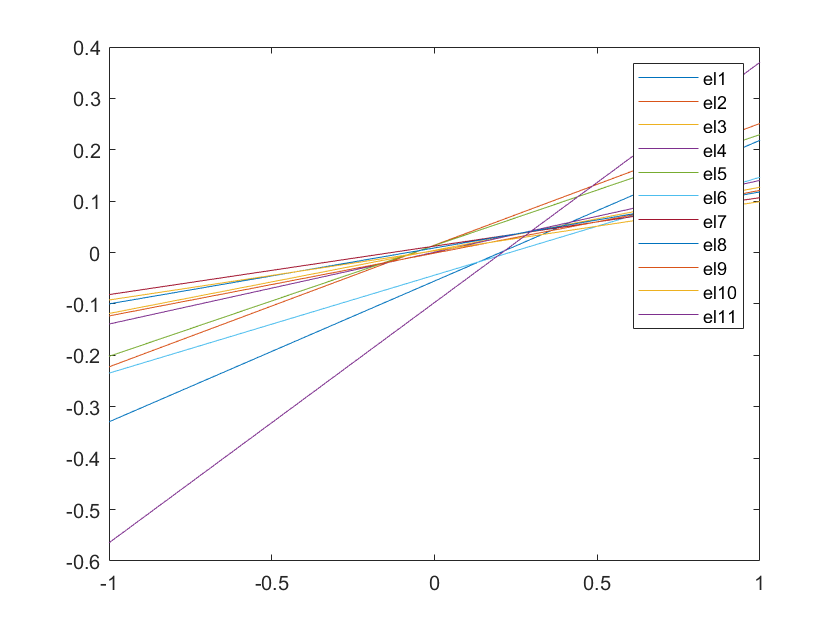

number_of_divisions_per_element = 21;


div = number_of_divisions_per_element;

[temperature_field,stress_field,dudx_field] = calc_Fields(temperature,displacements,numberElements,div,elementNodes,xx,yy,alpha,E);
         div=2/(div-1);
         iterator=[-1:div:1]; 
%          stress_field=stress_field
         
        plot(iterator',stress_field/10e10)
        legend("el1","el2","el3","el4","el5","el6","el7","el8","el9","el10","el11")

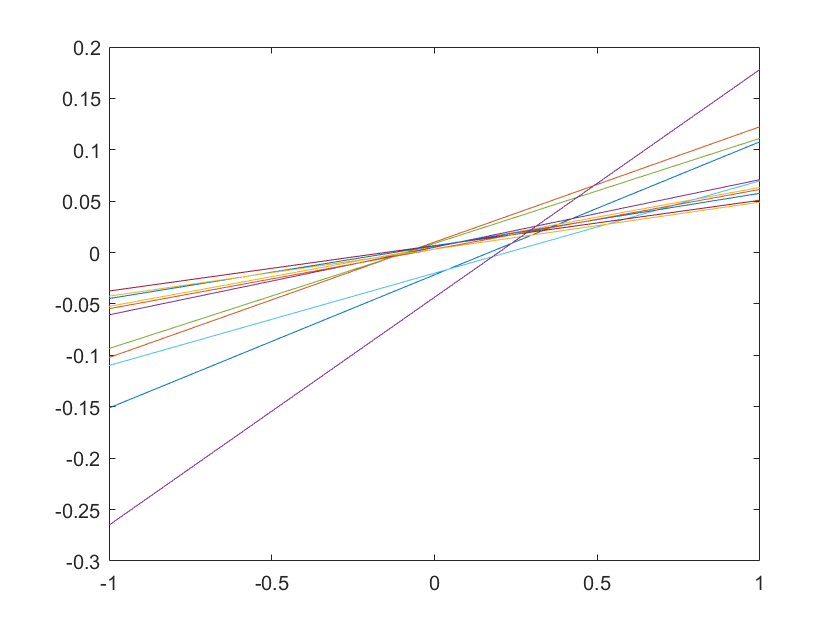

        plot(iterator',dudx_field)        

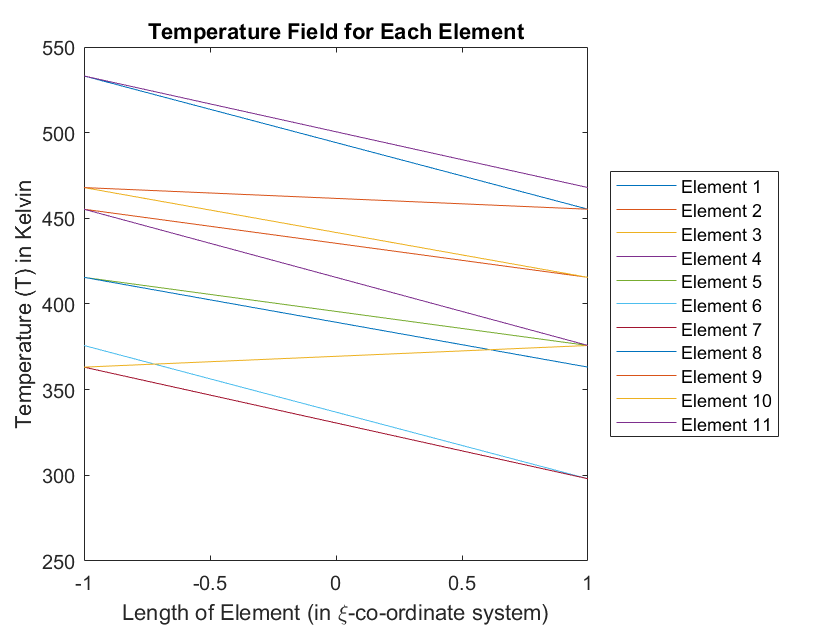

%         legend("el1","el2","el3","el4","el5","el6","el7","el8","el9","el10","el11")
% title('Strain Field for Each Element')
% xlabel('Length of Element (in \xi-co-ordinate system)')
% ylabel('Strain (\epsilon)')
% legend({'Element 1','Element 2','Element 3','Element 4','Element 5','Element 6','Element 7','Element 8','Element 9','Element 10','Element 11'},'Location','eastoutside')
        plot(iterator,temperature_field)
%         legend("el1","el2","el3","el4","el5","el6","el7","el8","el9","el10","el11")
title('Temperature Field for Each Element')
xlabel('Length of Element (in \xi-co-ordinate system)')
ylabel('Temperature (T) in Kelvin')
legend({'Element 1','Element 2','Element 3','Element 4','Element 5','Element 6','Element 7','Element 8','Element 9','Element 10','Element 11'},'Location','eastoutside')

## Yield stress matrix

## Functions used

        function stiffness = formStiffnessTemp(GDof,numberElements,numberNodes,elementNodes,K,A,L,xx,yy)

    stiffness = zeros(GDof); % Global Stiffness Matrix initialisation
    syms xi; % The bi-Domain Variable
    temp = [2*xi-1;-4*xi;2*xi+1]; % Template for gauss quadrature;
    temp = temp*temp';

    for e = 1:numberElements
        
        indice = elementNodes(e,:);
        xa = xx(indice(3)) - xx(indice(1)); %(delta x)
        ya = yy(indice(3)) - yy(indice(1));
        l = sqrt(xa^2 + ya^2); % length of element;
        
        Ke = zeros(3);
        for i=1:3
            for j = 1:3;
                Ke(i,j) = K*A/(2*l)*Gauss2point(temp(i,j));
            end
        end
        
        stiffness(indice,indice) = stiffness(indice,indice) + Ke; % Assembly of Global Stiffness
        
    end 
end


function [Ku,Kt] = formStiffnessCombined(GDofc,numberElements,numberNodes,elementNodes,E,A,L,xx,yy,alpha)

    Ku = zeros(GDofc);
    Kt = zeros(GDofc);
    syms xi
    N = [xi*(xi-1)/2;(1-xi^2);xi*(1+xi)/2]; % Template for gauss quadrature;
    Nd = diff(N,xi);
    NdNd = Nd*Nd';
    NdN = N*Nd';
    
     
    for e = 1:numberElements
        
        indice = elementNodes(e,:);
        elementDof = [2*indice(1)-1, 2*indice(1), 2*indice(2)-1, 2*indice(2), 2*indice(3)-1, 2*indice(3)];
        xa = xx(indice(3)) - xx(indice(1)); %(delta x)
        ya = yy(indice(3)) - yy(indice(1));
        l = sqrt(xa^2 + ya^2); % length of element;
        
        c = xa/l;
        s = ya/l;
        
        L1 = [c s 0 0 0 0;0 0 c s 0 0;0 0 0 0 c s];
        L2 = 0.5*[1 1 0 0 0 0;0 0 1 1 0 0;0 0 0 0 1 1];
        
        Kue = zeros(3);
        Kte = zeros(3);
        for i = 1:3
            for j = 1:3
                Kue(i,j) = E*A/(2*l)*Gauss2point(NdNd(i,j));
                Kte(i,j) = E*A*alpha*Gauss2point(NdN(i,j));
            end
        end
             
        Kue = L1'*Kue*L1;
        Kte = L2'*Kte*L2;
        
        Ku(elementDof,elementDof) = Ku(elementDof,elementDof) + Kue;
        Kt(elementDof,elementDof) = Kt(elementDof,elementDof) + Kte;
        
    end
end


function [Kt] = formKt(GDofc,numberElements,numberNodes,elementNodes,E,A,L,xx,yy,alpha)


    Kt = zeros(GDofc);
    syms xi
    N = [xi*(xi-1)/2;(1-xi^2);xi*(1+xi)/2]; % Template for gauss quadrature;
    Nd = diff(N,xi);
    NdNd = Nd*Nd';
    NdN = N*Nd';
     
    for e = 1:numberElements
        
        indice = elementNodes(e,:);
        elementDof = [2*indice(1)-1, 2*indice(1), 2*indice(2)-1, 2*indice(2), 2*indice(3)-1, 2*indice(3)];
        xa = xx(indice(3)) - xx(indice(1)); %(delta x)
        ya = yy(indice(3)) - yy(indice(1));
        l = sqrt(xa^2 + ya^2); % length of element;
        
        c = xa/l;
        s = ya/l;
        
        L1 = [c s 0 0 0 0;0 0 c s 0 0;0 0 0 0 c s];
        L2 = 0.5*[1 1 0 0 0 0;0 0 1 1 0 0;0 0 0 0 1 1];

        Kte = zeros(3);
        for i = 1:3
            for j = 1:3
                Kte(i,j) = -1*2*E*A*alpha/l*Gauss2point(NdN(i,j));
            end
        end
        
        
        
%         Kte = Kte + E*A*alpha*[-1 0 0;0 0 0;0 0 1];
       

        Kte = L2'*Kte*L2;
        

        Kt(elementDof,elementDof) = Kt(elementDof,elementDof) + Kte;
        
    end
end

function [Ku,RHS1,RHS_Temp] = formKu(GDofc,numberElements,numberNodes,elementNodes,E,A,L,xx,yy,alpha,RHS)

    Ku = zeros(GDofc);
    RHS_Temp = zeros(size(RHS));
    RHS1 = RHS;
    
    syms xi
    N = [xi*(xi-1)/2;(1-xi^2);xi*(1+xi)/2]; % Template for gauss quadrature;
    Nd = diff(N,xi);
    NdNd = Nd*Nd';
    NdN = N*Nd';
    
     
    for e = 1:numberElements
        
        indice = elementNodes(e,:);
        elementDof = [2*indice(1)-1, 2*indice(1), 2*indice(2)-1, 2*indice(2), 2*indice(3)-1, 2*indice(3)];
        xa = xx(indice(3)) - xx(indice(1)); %(delta x)
        ya = yy(indice(3)) - yy(indice(1));
        l = sqrt(xa^2 + ya^2); % length of element;
        
        c = xa/l;
        s = ya/l;
        
        L1 = [c s 0 0 0 0;0 0 c s 0 0;0 0 0 0 c s];
        L2 = 0.5*[1 1 0 0 0 0;0 0 1 1 0 0;0 0 0 0 1 1];
        
        Kue = zeros(3);
        for i = 1:3
            for j = 1:3
                Kue(i,j) = E*A/(2*l)*Gauss2point(NdNd(i,j));
            end
        end
        
        Kue(:,1) = Kue(:,1) + 0.5*Kue(:,2);
        Kue(:,3) = Kue(:,3) + 0.5*Kue(:,2);
        Kue(2,:) = 0;
        Kue(:,2) = 0;
       
        Kue = L1'*Kue*L1;
        
        middleDof = elementDof(3:4);
        RHS_Temp(middleDof) = RHS(middleDof);
        RHS1(middleDof) = 0;
        
        Ku(elementDof,elementDof) = Ku(elementDof,elementDof) + Kue;
        
    end
end

function displacement1 = findIntermediateDisplacement(RHS_Temp,T,displacement,GDofc,numberElements,numberNodes,elementNodes,E,A,L,xx,yy,alpha,RHS,nodesToRemove)
    displacement1 = displacement;
    for e = 1:numberElements
        indice = elementNodes(e,:);
        elementDof = [2*indice(1)-1, 2*indice(1), 2*indice(2)-1, 2*indice(2), 2*indice(3)-1, 2*indice(3)];
         xa = xx(indice(3)) - xx(indice(1)); %(delta x)
        ya = yy(indice(3)) - yy(indice(1));
        l = sqrt(xa^2 + ya^2); % length of element;
         c = xa/l;
        s = ya/l;
        displacement1(2*indice(2)-1)= -1*c*3*l*alpha*2/3*(T(2*indice(1))+T(2*indice(2)))+3/8*4/3*(displacement1(2*indice(1)-1)+displacement1(2*indice(3)-1));
        displacement1(2*indice(2))= -1*s*3*l*alpha*2/3*(T(2*indice(1))+T(2*indice(2)))+3/8*4/3*(displacement1(2*indice(1))+displacement1(2*indice(3)));
        
        
    end

end


function [temperature_field,stress_field,dudx_field] = calc_Fields(temperature,displacements,numberElements,div,elementNodes,xx,yy,alpha,E)

    temperature_field = zeros(div,numberElements);
    dudx_field = zeros(div,numberElements);
    div=2/(div-1);
         iterator=[-1:div:1];
        [m,n]=size(iterator);
        stress_field=zeros(n,numberElements);    
    
    for e = 1:numberElements
        indice = elementNodes(e,:);
        elementDof = [2*indice(1)-1, 2*indice(1), 2*indice(2)-1, 2*indice(2), 2*indice(3)-1, 2*indice(3)];
        xa = xx(indice(3)) - xx(indice(1)); %(delta x)
        ya = yy(indice(3)) - yy(indice(1));
        l = sqrt(xa^2 + ya^2); % length of element;
         c = xa/l;
        s = ya/l;  
        syms xi;
        shape_function1=xi*(xi-1)/2;
        shape_function2=(1-xi^2);
        shape_function3=xi*(1+xi)/2;
              
        T = temperature(indice(1))*shape_function1+temperature(indice(2))*shape_function2+temperature(indice(3))*shape_function3;
        U_x=displacements(2*indice(1)-1)*shape_function1+displacements(2*indice(2)-1)*shape_function2+displacements(2*indice(3)-1)*shape_function3;
        U_y=displacements(2*indice(1))*shape_function1+displacements(2*indice(2))*shape_function2+displacements(2*indice(3))*shape_function3;
        U=(displacements(2*indice(1)-1)*c+displacements(2*indice(1))*s)*shape_function1+(displacements(2*indice(2)-1)*c+displacements(2*indice(2))*s)*shape_function2+(displacements(2*indice(3)-1)*c+displacements(2*indice(3))*s)*shape_function3;
        strain=diff(U)*l/2;
        stress_field_function=E*(strain-alpha*(T-298));
            
         for i=1:n
            dudx_field(i,e)=subs(strain,iterator(1,i));
        end
        for i=1:n
            temperature_field(i,e)=subs(T,iterator(1,i));
        end
        for i=1:n
            stress_field(i,e)=subs(stress_field_function,iterator(1,i));
        end     
        
    end
    

end



function A = Gauss2point(exp)
    temp = 1/sqrt(3); % Gauss Quadrature Point
    A = subs(exp,temp) + subs(exp,-1*temp);
end

function plotter(xx,yy,elementNodes,numberElements)
    hold on
    for i = 1:numberElements
        Nodes = elementNodes(i,:);
        Nodei = Nodes(1);
        Nodej = Nodes(2);
        
        x = [xx(Nodei) xx(Nodej)];
        y = [yy(Nodei) yy(Nodej)];
        
        plot(x,y)
        
        Nodei = Nodes(2);
        Nodej = Nodes(3);
        
        x = [xx(Nodei) xx(Nodej)];
        y = [yy(Nodei) yy(Nodej)];

%         Nodei = Nodes(1);
%         Nodej = Nodes(3);
%         
%         x = [xx(Nodei) xx(Nodej)];
%         y = [yy(Nodei) yy(Nodej)];
        
        plot(x,y)
    end
    hold off
end